# Analysis of social, multi-flavor experiment on 2/10/2024

## Data import

#### Root directory

rootdir = 'Z:\users\Tatsumi\data\MultiReward\singlebat\14662\240209';
ephys_rootdir = 'Z:\users\Tatsumi\data\MultiReward\singlebat\14662\240209\ephys\20240209_142859.rec'; % the root directory of all merged rec files
cd(rootdir)

### Subdirectory

% preprocessing
% run PreprocessAllEphys.m
% run PreprocessBhvData.m

% output directory
analysis_dirpath     =   fullfile(rootdir,'analysis');
% Figure
fig_dirpath    =   fullfile(analysis_dirpath,'figure');

### Experiment info

mtData.rec_date = '240209'; % recording date
mtData.rec_type = 'untethered'; % recording type
mtData.exp_type = 'solitary,multi-flavor'; % experiment type

% Bat subjects
mtData.bname = {"14662"}; % in order of serial number list
mtData.bname_ephys = {'14662'}; % ephys bat

% reward
mtData.reward_list = {"banana","pear","grape","melon"};
mtData.reward_session = [1,2,0,0; 2,1,0,0];
save(fullfile(rootdir,'analysis','exp_info.mat'),'mtData')

### Preprocess and load behavioral data

[BhvData, AnalogData] = PreprocessBhvData(rootdir);

Extracted data are found in the directory.
Behavior data are found in the directory.
Analog signal data are found.


Final MinPeakDistance was 1.0 
25 peaks were detected. 
1 artifacts were detected. It matches with the number of sessions. 
All rewarding landings were recorded and detected.


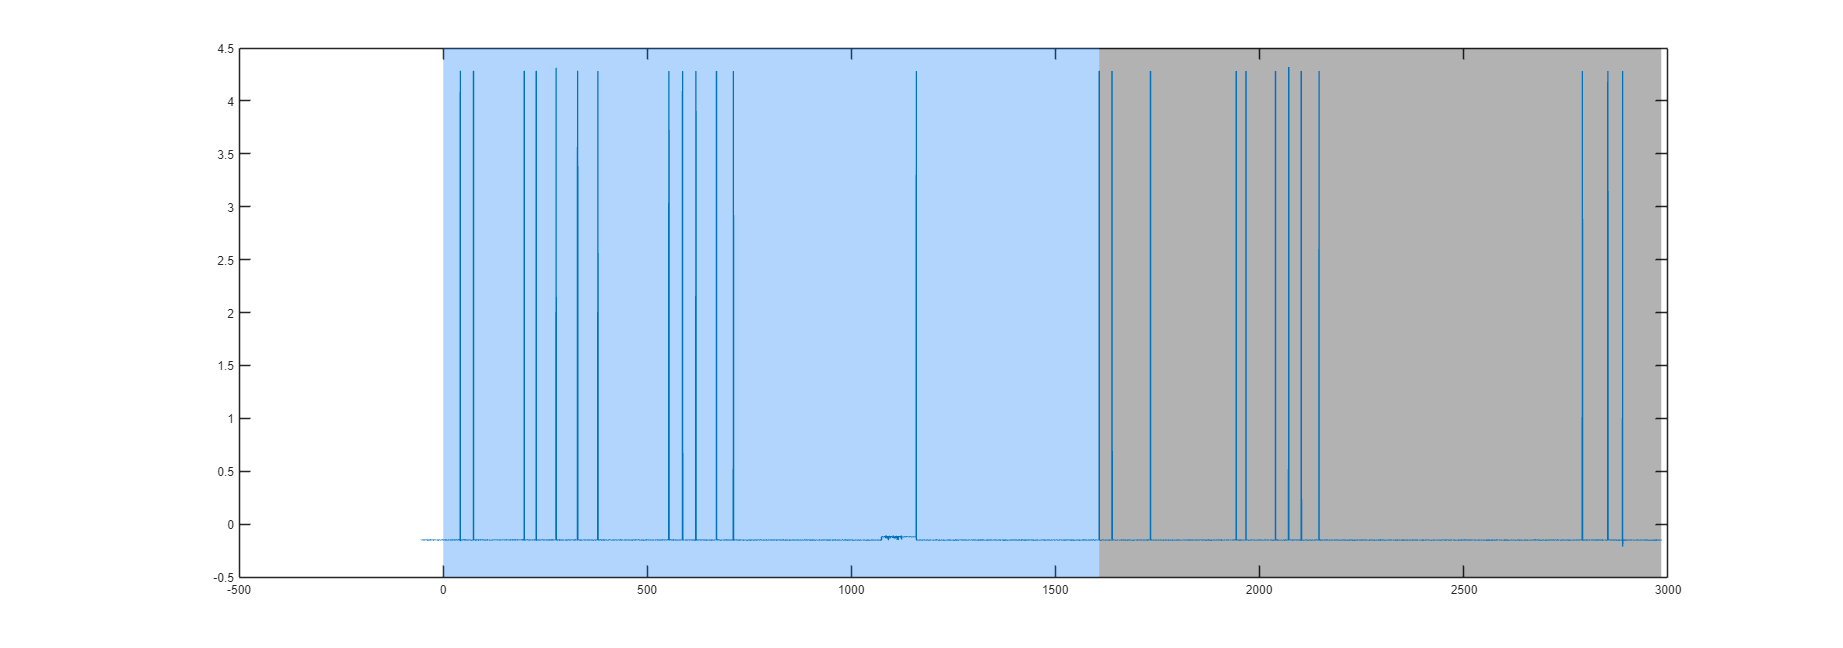

RewardData = PreprocessRewardData(rootdir);

## Data Visualization

### Detect takeoff/landings based on the cdp data

Extract the start/end timings and the position of all the landings/flights. The extracted information is saved into `Landings/Flights`

Landings = extractLandings(BhvData,RewardData,'include','all');
for bb = 1:length(Landings)
    n_land = Landings(bb).n_land;
    fprintf('%dth bat: %d landing were detected. \n',bb, n_land)
end

1th bat: 60 landing were detected. 



% feeder landings
Landings_fd = extractLandings(BhvData,RewardData,'include','feeder');
for bb = 1:length(Landings_fd)
    n_land = Landings_fd(bb).n_land;
    fprintf('%dth bat: %d landing were detected. \n',bb, n_land)
end

1th bat: 25 landing were detected. 


#### Clustering the flight trajectories

% Hierarchical clustering of trajectories
% hc = TrajClusteringHC(Landings,'cutoff',1,'minpts',2,'n_smp',50,'n_dim',3);
% FigDir = fullfile(pwd,'analysis','figure','ClusteredTrajectory_HC');
% PlotClusteredTrajectory(TrjCluster,'FigDir',FigDir)

% DBSCAN clustering of trajectories
TrjCluster = TrajClusteringDBSCAN(Landings,'minpts',2,'n_smp',100,'n_dim',2);
FigDir = fullfile(pwd,'analysis','figure','ClusteredTrajectory_DBSCAN');
PlotClusteredTrajectory(TrjCluster,'FigDir',FigDir)

### Feeder/reward preference based on the cdp data

Feeder preference

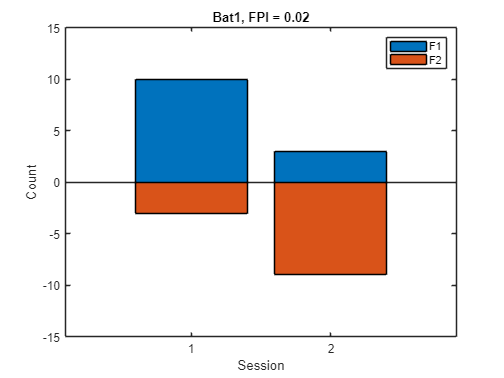

% Load data
Landings_fd = extractLandings(BhvData,RewardData,'include','feeder'); % landings
n_session = size(mtData.reward_session,1); % number of sessions
n_bats = length(mtData.bname); % number of bats
n_feeder = 2; % number of feeders

%%% FIGURE: feeder preference
% fig = figure;
% fontsize(fig, 24, "points")
% set(fig, 'units','normalized','Position',[0.2 0.2 0.6 0.4]);
% tiledlayout(2,5,"TileSpacing",'compact')
for bb = 1:n_bats   
    % Compute preference for feeder and/or reward. 
    % Feeder/reward preference index (PI), defined as (|F1-F2|/|F1+F2|) where F1 or F2 is the counts of landings on the feeder 1 or feeder 2.
    % The range is -1 < PI < 1. The larger PI means that the bat prefers to the feeder 1, while the lower PI means that the bat does the feeder 2.
    % PI = 0 means that there is no preference.

    % Feeder preference
    X = Landings_fd(bb).session_land;
    Y = Landings_fd(bb).closest_feeder(:,2);
    [feeder_pref, feeder_pref_index] = computePreferenceIndex(X,Y,n_session,n_feeder);

    feeder_pref(:,2) = feeder_pref(:,2)*-1;

    % reward_pref = zeros(n_session,2);
    % feeder_pref = zeros(n_session,2);
    % for ss = 1:n_session
    %     for ff = 1:2 % number of active feeder
    %         feeder_pref(ss,ff) = sum(Landings_fd(bb).session_land==ss & Landings_fd(bb).closest_feeder(:,2)==ff);
    %     end
    % 
    %     for flavor = 1:2 % number of flavor types
    %         reward_pref(ss,flavor) = sum(Landings_fd(bb).session_land == ss & Landings_fd(bb).reward == flavor);
    %     end
    % end
    % feeder_pref(:,2) = feeder_pref(:,2)*-1;
    % reward_pref(:,2) = reward_pref(:,2)*-1;
    
    % Feeder/reward preference index (PI), defined as (|F1-F2|/|F1+F2|) where F1 or F2 is the counts of landings on the feeder 1 or feeder 2.
    % The range is -1 < PI < 1. 
    % The larger PI means that the bat prefers to the feeder 1, while the
    % lower PI means that the bat does the feeder 2. PI = 0 means that
    % there is no preference
    % feeder_pref_index = -1*diff(abs(feeder_pref),1,2)./sum(abs(feeder_pref),2); 
    % reward_pref_index = -1*diff(abs(reward_pref),1,2)./sum(abs(reward_pref),2); 

    max_cnt = max(max(abs(feeder_pref)));

    % FIGURE
    fig = figure;
    fontsize(fig, 24, "points")
    % nexttile
    bar(categorical(1:n_session),feeder_pref,'stacked')
    title(sprintf('Bat%s, FPI = %.2f',num2str(bb),mean(feeder_pref_index,'omitnan')))
    xlabel('Session')
    ylabel('Count')
    legend({"F1","F2"})
    ylim([-1*(max_cnt+5),max_cnt+5])
end
% Figure directory
FigDir = fullfile(fig_dirpath,'feeder_preference');
if isempty(dir(FigDir))
    mkdir(FigDir)
end
saveas(fig,fullfile(FigDir,'Feeder_preference_cdp.png'))

Reward preference

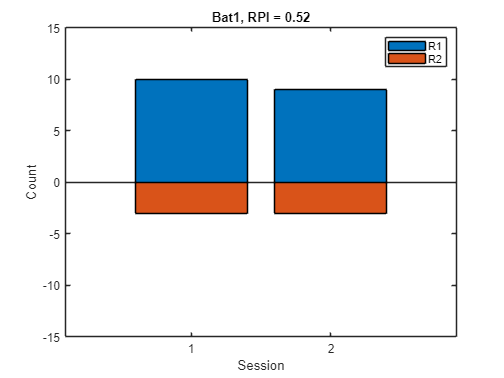

% Load data
Landings_fd = extractLandings(BhvData,RewardData,'include','feeder'); % landings
n_session = size(mtData.reward_session,1); % number of sessions
n_bats = length(mtData.bname); % number of bats
n_reward = 2; % number of types of reward

%%% FIGURE: feeder preference
% fig = figure;
% fontsize(fig, 24, "points")
% set(fig, 'units','normalized','Position',[0.2 0.2 0.6 0.4]);
% tiledlayout(2,5,"TileSpacing",'compact')
% for bb = 1:n_bats   
    % Compute preference for feeder and/or reward. 
    % Feeder/reward preference index (PI), defined as (|F1-F2|/|F1+F2|) where F1 or F2 is the counts of landings on the feeder 1 or feeder 2.
    % The range is -1 < PI < 1. The larger PI means that the bat prefers to the feeder 1, while the lower PI means that the bat does the feeder 2.
    % PI = 0 means that there is no preference.

    % Reward preference
    X = Landings_fd(bb).session_land;
    Y = Landings_fd(bb).reward;
    [reward_pref, reward_pref_index] = computePreferenceIndex(X,Y,n_session,n_reward);

    reward_pref(:,2) = reward_pref(:,2)*-1;

    max_cnt = max(max(abs(reward_pref)));

    % FIGURE
    % nexttile
        fig = figure;
    fontsize(fig, 24, "points")
    bar(categorical(1:n_session),reward_pref,'stacked')
    title(sprintf('Bat%s, RPI = %.2f',num2str(bb),mean(reward_pref_index,'omitnan')))
    xlabel('Session')
    ylabel('Count')
    legend({"R1","R2"})
    ylim([-1*(max_cnt+5),max_cnt+5])
% end
% Figure directory
FigDir = fullfile(fig_dirpath,'feeder_preference');
if isempty(dir(FigDir))
    mkdir(FigDir)
end
saveas(fig,fullfile(FigDir,'Reward_preference_cdp.jpg'))

#### Cumulative preference plot

Cumulative plot for the feeder preference

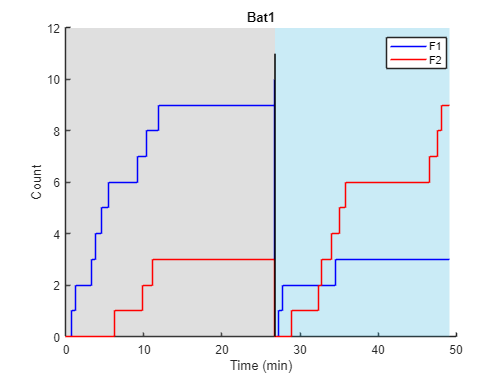

Landings_fd = extractLandings(BhvData,RewardData,'include','feeder'); % landings
t_session = RewardData.t_session_sec; % time of the start of sessions in sec
t = BhvData.t; % timestamps for behavior data
n_session = size(mtData.reward_session,1); % number of sessions
n_bats = length(mtData.bname); % number of bats

%%% FIGURE: cumulative plot of feeder landings
fig = figure;
fontsize(fig, 24, "points")
% set(fig, 'units','normalized','Position',[0.2 0.2 0.6 0.4]);
% tiledlayout(2,5,"TileSpacing",'compact')
fig_clr = {'b','r'};
% for bb = 1:n_bats
%     nexttile
    hold on
    for ff = 1:2 % number of active feeder
        
        t_rw_cum_sec = []; % time of reward delivery in sec
        reward_cum = []; % cumulative count of reward delivery
        
        for ss = 1:n_session
            t_rw_cum_sec = [t_rw_cum_sec; t_session(ss)];
            reward_cum = [reward_cum; 0];
            
            idx = Landings_fd(bb).closest_feeder(:,2)==ff & Landings_fd(bb).session_land == ss; % index for the current feeder
            t_rw_cum_sec = [t_rw_cum_sec; Landings_fd(bb).t_land_sec(idx)];
            reward_cum = [reward_cum;cumsum(ones(sum(idx),1))];
        end
        t_rw_cum_sec = [t_rw_cum_sec; t(end)];
        t_rw_cum_min = t_rw_cum_sec / 60; % convert to minutes
        reward_cum = [reward_cum; reward_cum(end)];
    
        stairs(t_rw_cum_min,reward_cum,'Color',fig_clr{ff})
    end
    title(sprintf('Bat%s',num2str(bb)))
    xlabel('Time (min)')
    ylabel('Count')
    
    % Draw the boundary of session
    y_lim = ylim;
    for ss = 2:n_session
        plot([t_session(ss)/60,t_session(ss)/60],[y_lim(1),y_lim(2)+1],'k')
    end

    for session = 1:n_session
        if mod(session,2) == 0
            if session ~= n_session
                xregion(t_session(session)/60,t_session(session+1)/60,'FaceColor',[80,190,225]/255)
            else
                xregion(t_session(session)/60,t(end)/60,'FaceColor',[80,190,225]/255)
            end
        else
            if session ~= n_session
                xregion(t_session(session)/60,t_session(session+1)/60,'FaceColor',[150,150,150]/255)
            else
                xregion(t_session(session)/60,t(end)/60,'FaceColor',[150,150,150]/255)
            end
        end
    end

    hold off

    f=get(gca,'Children');
    legend([f(length(f)),f(length(f)-1)],'F1','F2')
% end

% Figure directory
FigDir = fullfile(fig_dirpath,'feeder_preference');
if isempty(dir(FigDir))
    mkdir(FigDir)
end
saveas(gcf,fullfile(FigDir,'Cumulative_feeder_preference_cdp.png'))

Cumulative plot for the reward preferences

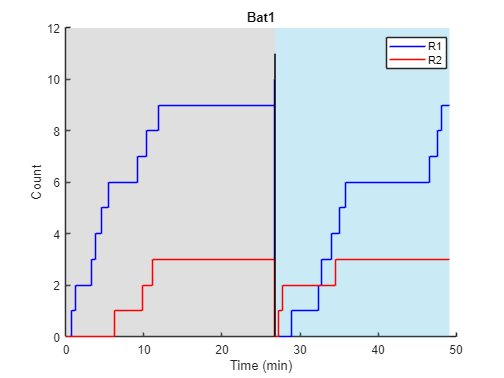

Landings_fd = extractLandings(BhvData,RewardData,'include','feeder'); % landings
t_session = RewardData.t_session_sec; % time of the start of sessions in sec
t = BhvData.t; % timestamps for behavior data
n_session = size(mtData.reward_session,1); % number of sessions
n_bats = length(mtData.bname); % number of bats

%%% FIGURE: cumulative plot of feeder landings
fig = figure;
fontsize(fig, 24, "points")
% set(fig, 'units','normalized','Position',[0.2 0.2 0.6 0.4]);
% tiledlayout(2,5,"TileSpacing",'compact')
fig_clr = {'b','r'};


% for bb = 1:n_bats
%     nexttile
    hold on
    for ff = 1:2 % number of flavor types
        
        t_rw_cum_sec = []; % time of reward delivery in sec
        reward_cum = []; % cumulative count of reward delivery
        
        for ss = 1:n_session
            t_rw_cum_sec = [t_rw_cum_sec; t_session(ss)];
            reward_cum = [reward_cum; 0];
            
            idx = Landings_fd(bb).reward==ff & Landings_fd(bb).session_land == ss; % index for the current reward
            t_rw_cum_sec = [t_rw_cum_sec; Landings_fd(bb).t_land_sec(idx)];
            reward_cum = [reward_cum;cumsum(ones(sum(idx),1))];
        end
        t_rw_cum_sec = [t_rw_cum_sec; t(end)];
        t_rw_cum_min = t_rw_cum_sec / 60; % convert to minutes
        reward_cum = [reward_cum; reward_cum(end)];
    
        stairs(t_rw_cum_min,reward_cum,'Color',fig_clr{ff})
    end
    title(sprintf('Bat%s',num2str(bb)))
    xlabel('Time (min)')
    ylabel('Count')
    
    % Draw the boundary of session
    y_lim = ylim;
    for ss = 2:n_session
        plot([t_session(ss)/60,t_session(ss)/60],[y_lim(1),y_lim(2)+1],'k')
    end

    for session = 1:n_session
        if mod(session,2) == 0
            if session ~= n_session
                xregion(t_session(session)/60,t_session(session+1)/60,'FaceColor',[80,190,225]/255)
            else
                xregion(t_session(session)/60,t(end)/60,'FaceColor',[80,190,225]/255)
            end
        else
            if session ~= n_session
                xregion(t_session(session)/60,t_session(session+1)/60,'FaceColor',[150,150,150]/255)
            else
                xregion(t_session(session)/60,t(end)/60,'FaceColor',[150,150,150]/255)
            end
        end
    end

    hold off

    f=get(gca,'Children');
    legend([f(length(f)),f(length(f)-1)],'R1','R2')
% end

% Figure directory
FigDir = fullfile(fig_dirpath,'feeder_preference');
if isempty(dir(FigDir))
    mkdir(FigDir)
end
saveas(gcf,fullfile(FigDir,'Cumulative_reward_preference_cdp.jpg'))